# Inverse Kinematics 

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

We have demonstrated how forward kinematics can be modeled using DH Parameters in the [previous section](matlab:open('./ForwardKinematics.mlx')). In addition, we utilized simulation to interact with a robot arm to understand the placement of the end-effector using known joint angles. This section will focus on the reverse process, calculating a robot's inverse kinematics. This process calculates the joint angles from a known position and orientation of the end-effector. 

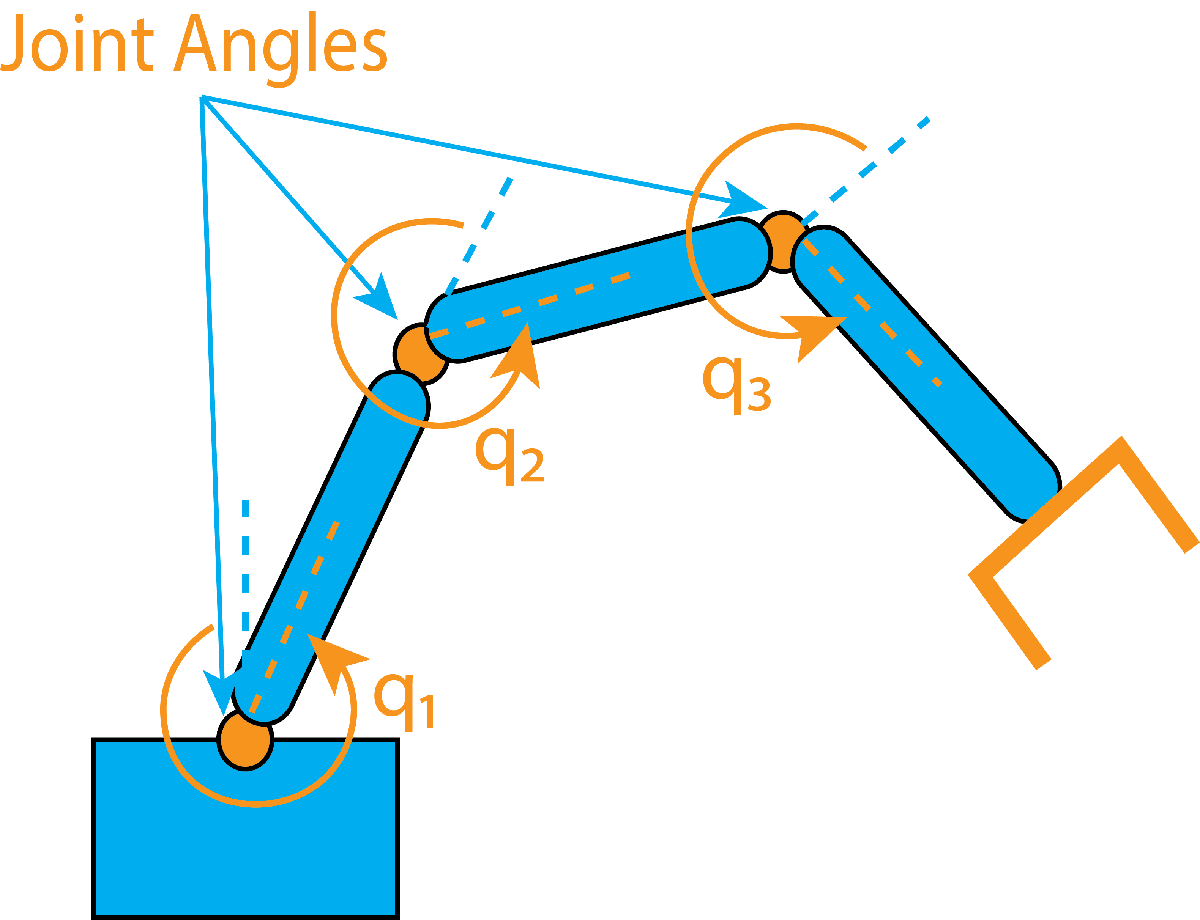

In this script, you will calculate the inverse kinematics of a robot to determine the joint positions. 

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if they run out of order.

## Inverse Kinematics Background

Inverse kinematics aims to obtain the robot's joint angles by utilizing the position and orientation of a robot's end-effector, thus defining the robot's motion path. Because of this, the robot's motion is centered around the end-effector. This means each joint will move with respect to the location of the end-effector. Each joint rotates together, creating line trajectories for the robot. For example, pictured below is a 3-joint robot. Moving the end-effector to a given location will rotate joints 1, 2, and 3 simultaneously, producing a line movement. This type of action more closely represents how we move our arms to complete a task. When you obtain the end-effector's final location, you can determine the joint angles that made it possible to achieve that location.

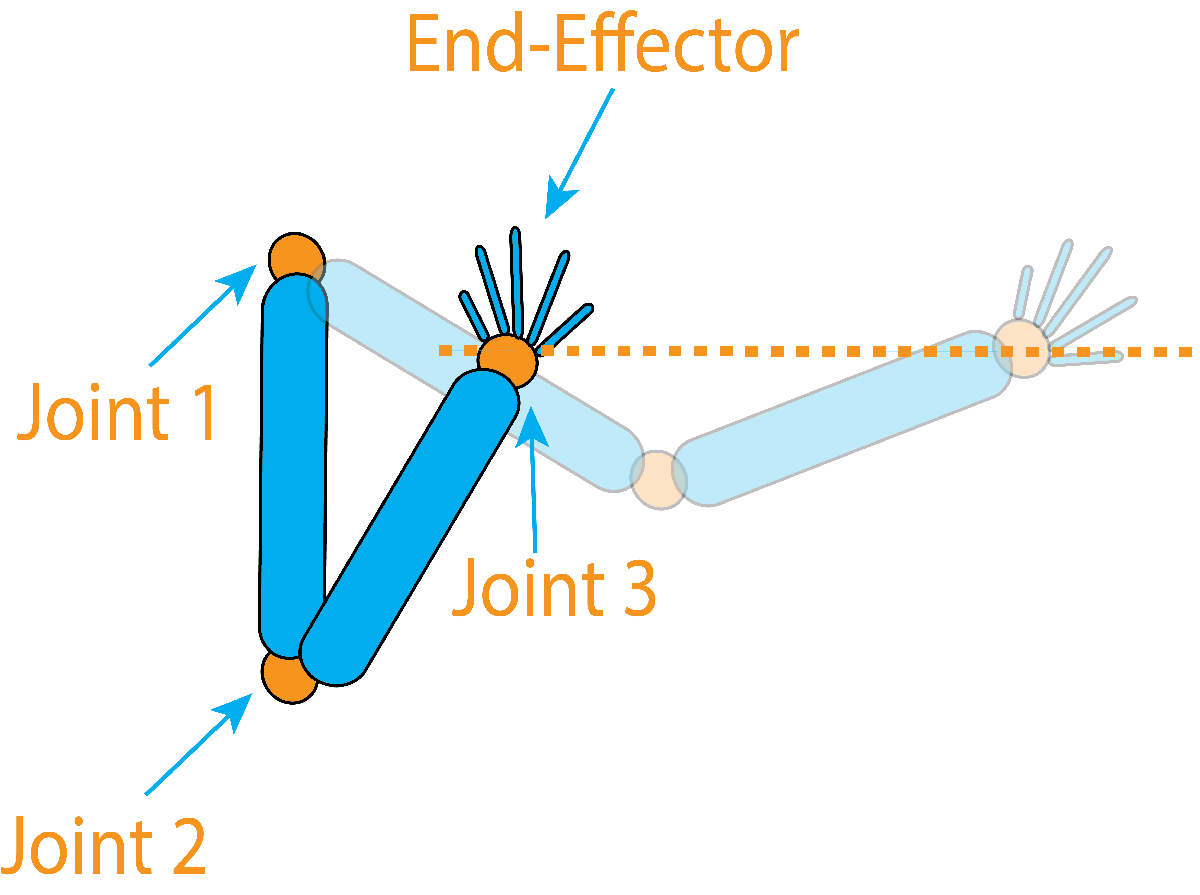

**Activity**. Practice inverse kinematics! First, sit down in a chair at a table. Next, hold your arm stiffly next to your body. Consider your shoulder as Joint 1, your elbow as Joint 2, and your wrist as Joint 3. Now, try to pick up an object on the table by only moving your arm in straight lines. Return to the forward kinematics module, try the [activity](matlab:open('./Forward_Kinematics.mlx')) there, and see if you can tell the difference.

### The Challenges with Inverse Kinematics

Inverse kinematics [1] is more challenging to work with than forward kinematics because there are usually multiple solutions (combinations of joint angles) that can achieve the desired end-effector target location; the manipulator in the image above is one example. In addition, you may have bounds and limits in which your manipulator can operate. That is, one joint may have a smaller range of operating angles than another and would need to be optimized simultaneously to achieve the end-effector's final position and orientation. A few classifications of robots define how good of an inverse kinematic solution you will have for a given target location. For instance, under-actuated robots may reach the target position but not the orientation of the end-effector. Meanwhile, fully actuated robots may have multiple ways to reach the target position and orientation. Then, there are redundant robots that can have an infinite number of solutions that achieve the target position and orientation. These types are shown in the following table:

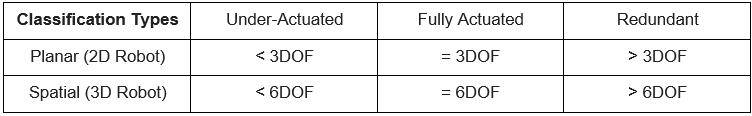

This problem becomes exceedingly more difficult as you increase the number of joints (DOF) in the manipulator. Because of these challenges, mathematicians use two primary approaches to solve the inverse kinematics problem. Each approach has two specific methods to choose from:

- Analytical Solutions (Algebraic, Geometric) - Derived equations solving for joint angles, which are a function of the end-effector location

- Approximate Solutions (Jacobian Inverse, Cyclic Coordinate Descent) - Iterative method of numerically computing joint angles by moving closer to the end-effector location each iteration

It is important to understand when you should consider using one approach over the other:

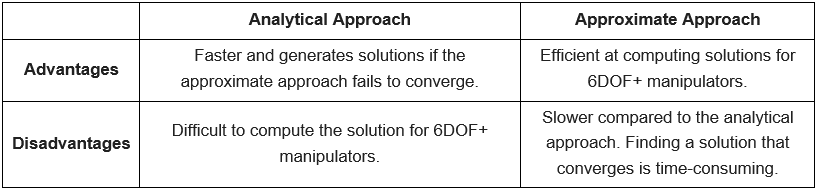

This module will focus on the approximate solution (Jacobian Inverse). The method we will use in this example assumes a fully actuated spatial robot. You can find information on the other methods in the Further Exploration section. For the Jacobian Inverse, we will require the end location of the end-effector and the transformation matrices calculated from the forward kinematics. Recall that the transformation matrix comprises the rotation (3x3) and translation (3x1) matrices.

### Jacobian Inverse Method 

The Jacobian Inverse Method is the most widely used iterative technique in solving inverse kinematic problems. The first step is to compute the Jacobian matrix as a function of the transformation matrices (specifically, the joint angles) and then take its inverse. Then, we can iterate on the end-effector's current location until its target location is achieved. As this happens, the joint angles will change slowly to move the robot arm to its final location within some tolerance. This means that with new joint angles, we will have to calculate new forward kinematics (new transformation matrices) for the next location achieved by the end-effector. The Jacobian also depends on the forward kinematics and will change every iteration. In robotics, the Jacobian matrix ($J$) provides a direct correlation between the joint velocities ($\dot
X$) and the end-effector velocities ($\dot
q$):

#### 
$$\dot
X = J \dot
q$$


Therefore, the inverse Jacobian matrix satisfies the equation:

#### 
$$\dot
q = J^{-1}
\dot  X$$


Since we are dealing with joint angles instead of joint velocities, we require an expression that correlates the  joint positions ($\delta
q$) and end-effector displacement ($\delta  X$) instead:

#### 
$$\delta
q = J^{-1}
\delta  X$$


Where $\delta$ represents an incremental change in the end-effector position and joint angles. The number of rows in a Jacobian matrix depends on the type of robot and its DOF. Since we mentioned earlier that the robot is **spatial** and **fully actuated**, it will have 6DOF or six rows. The number of columns in a Jacobian matrix depends on the robot's number of joints. Therefore, the matrix will also have six columns, also known as a square matrix:

#### 
$$\left\lbrack \begin{array}{c}
{\delta q}_1 \\
{\delta q}_2 \\
{\delta q}_3 \\
{\delta q}_4 \\
{\delta q}_5 \\
{\delta q}_6 
\end{array}\right\rbrack ={\left\lbrack \begin{array}{cccccc}
J_{11}  & J_{12}  & J_{13}  & J_{14}  & J_{15}  & J_{16} \\
J_{21}  & J_{22}  & J_{23}  & J_{24}  & J_{25}  & J_{26} \\
J_{31}  & J_{32}  & J_{33}  & J_{34}  & J_{35}  & J_{36} \\
J_{41}  & J_{42}  & J_{43}  & J_{44}  & J_{45}  & J_{46} \\
J_{51}  & J_{52}  & J_{53}  & J_{54}  & J_{55}  & J_{56} \\
J_{61}  & J_{62}  & J_{63}  & J_{64}  & J_{65}  & J_{66} 
\end{array}\right\rbrack }^{-1} \cdot \left\lbrack \begin{array}{c}
\delta x\\
\delta y\\
\delta z\\
\delta \alpha \\
\delta \beta \\
\delta \gamma 
\end{array}\right\rbrack$$


Where:

-  $q_1 -q_6$ represents the incremental joint position changes and,

-  $x,y,z$ and $\alpha ,\beta ,\gamma$ represent the end-effector's linear position and rotational orientation, respectively. 

 **Note**. For under-actuated and redundant robots, the Jacobian matrix will always be non-square. That means the number of joints in the robot does not equal the number of DOFs.

### Finding the Jacobian Matrix

The vector $\delta X$ is split into two parts (linear and rotational) representing the end-effector's movement. The same is true for the Jacobian matrix:

            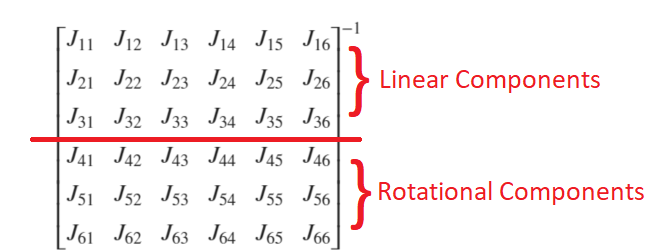

To find the linear and rotational elements of the Jacobian, we can use the following guide:

**   For Prismatic Joints**                                   **For Revolute Joints**

              Linear: $R_{i-1}^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$                                    Linear: $R_{i-1}^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack \times \left(d_n^0 -d_{i-1}^0 \right)$

Rotational: $\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$                                     Rotational: $R_{i-1}^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$

Where $i$ is the joint of interest and $n$ is the total number of joints in the robot. Observe the 3x1 vector multiplied by the rotational matrix in the prismatic or revolute case. This vector defines the joint's normal vector (or axis of rotation). This guide was written based on the assumption that each joint will rotate along the z-axis, hence the value of 1 in the 3rd position of the vector. It is essential to understand that this vector will vary based on the rotation of your joints. If you recall from the [DH Parameters module](matlab:open('./DHParameters.mlx')), we found the axis of rotation by assigning coordinate frames to each joint. 

Let's define the inverse Jacobian matrix for a spatial fully actuated robot (6DOF) with all revolute joints (and rotation of joints focused around the z-axis). Using the sample inverse Jacobian matrix above, we have the following 6x6 matrix:

#### 
$${\left\lbrack \begin{array}{cccccc}
J_{11}  & J_{12}  & J_{13}  & J_{14}  & J_{15}  & J_{16} \\
J_{21}  & J_{22}  & J_{23}  & J_{24}  & J_{25}  & J_{26} \\
J_{31}  & J_{32}  & J_{33}  & J_{34}  & J_{35}  & J_{36} \\
J_{41}  & J_{42}  & J_{43}  & J_{44}  & J_{45}  & J_{46} \\
J_{51}  & J_{52}  & J_{53}  & J_{54}  & J_{55}  & J_{56} \\
J_{61}  & J_{62}  & J_{63}  & J_{64}  & J_{65}  & J_{66} 
\end{array}\right\rbrack }^{-1} \Longrightarrow {\left\lbrack \begin{array}{cccccc}
R_0^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack \times \left(d_6^0 -d_0^0 \right) & R_1^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack \times \left(d_6^0 -d_1^0 \right) & R_2^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack \times \left(d_6^0 -d_2^0 \right) & R_3^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack \times \left(d_6^0 -d_3^0 \right) & R_4^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack \times \left(d_6^0 -d_4^0 \right) & R_5^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack \times \left(d_6^0 -d_5^0 \right)\\
R_0^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack  & R_1^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack  & R_2^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack  & R_3^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack  & R_4^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack  & R_5^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack 
\end{array}\right\rbrack }^{-1}$$


Observe the notation, $R_0^0$. This would represent the rotation from frame zero to itself. There is no rotation between the same frame; therefore, $R_0^0$ is expressed as the identity matrix. In addition, the displacement from the center of a frame to itself is also zero, therefore $d_0^0 =0$. The other components can be found from the transformation matrices found doing the forward kinematics of the robot. Meaning $R_{i-1}^0$, $d_n^0$, and $d_{i-1}^0$ can be found from $T_{i-1}^0$:

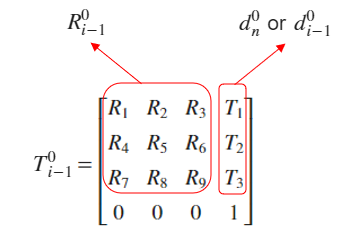

Rather than finding these components individually, there is a shortcut approach to finding the product of the rotation matrix $R_{i-1}^0$ (3x3) and the axis of rotation vector $\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$ (3x1). Using the coordinate frames of the joints to determine the axis of rotation, we can pull the resulting vector (3x1) of that product directly from the corresponding transformation matrix. For instance, if a joint is rotating about the Y-axis, the product of the rotation matrix and the axis of rotation vector is the second column of the transformation matrix:

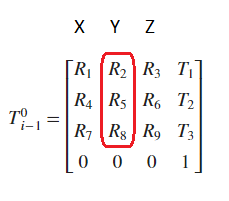

 **Note**. The DH parameters described and used in this script are based on the **standard convention**, not modified. For Modified DH parameters, please see the resource in the Further Exploration section. If you prefer to use the modified convention in this script, use CTRL+H to find and replace the `dh_param` function with the `moddh_param` function. Also, use the same method to change the loaded workspace variable from `FK_Exercise` to `FKMod_Exercise`. **DO NOT** change the function names in the Local Helper Functions section.

** Demonstration**. Let's use the Jacobian Inverse Method to solve the inverse kinematics of a spatial fully actuated (6DOF) PUMA 560 [2] robot, where the blue dot represents the end-effector:

             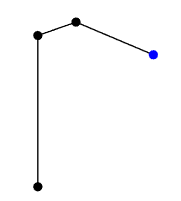                                          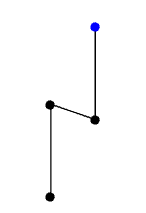

End-Effector Starting Location                                                    End-Effector Target Location

 **Note**. Recall the [discussion from the previous script](matlab:open('./Forward_Kinematics.mlx')) regarding the number of DOFs seen in the robot above compared to the DOFs present.

Let's start with the information we need to solve the inverse kinematics using the equation: $\delta
q = J^{-1}
\delta  X$. We need the end-effectors starting location, target location, joint angles, and forward kinematics (including the DH Parameters). The joint angles are used to calculate the transformation matrix (via DH Parameters) for the end-effector's current and target locations, $T_c \;\textrm{and}\;T_g$, respectively. We will import some data from the demonstration in the [Forward Kinematics module](matlab:open('./ForwardKinematics.mlx')) to perform the operations:

% Display parameters of the forward kinematics of the PUMA 560 robot
 

% Load parameters from forward kinematics script
load Data/FK_Exercise.mat

% Display parameters to user
whos('-file','Data/FK_Exercise.mat')

Next, we will take that data and display the current and target joint angles, $\theta_c \;\textrm{and}\;\theta_g$. We will also show the end-effector's current and target locations, $X_c \;\textrm{and}\;X_g$. These values are found in transformation matrices, $T_c \;\textrm{and}\;T_g$:

% Display the forward kinematics values of starting location
 

% Populate values and units for display table
[CurrentAngles,CurrentLocation,TargetAngles,TargetLocation] = popTable(Tc,Tg,jointAngles);

% Generate table of values for joint angles and position/orientation
pathDef = table(CurrentAngles,CurrentLocation,TargetAngles,TargetLocation)

The difference between $X_g \;\textrm{and}\;X_c$ is $\delta X
$. As the value of $\delta X
$ approaches zero, we know we are converging on a solution for the inverse kinematics. $\delta X
$ getting closer to zero means that $X_c$ incrementally moves closer to the target location, $X_g$, every iteration. $\delta X
$ is a 6x1 vector. The first three elements of the vector (the linear components) are where a tolerance will be applied because we are focused on the end-effector's position more than the orientation. Now that we have $\delta X
$, we need to calculate the Jacobian Matrix $\left(J\right)$ based on the current configuration of the robot:

% Display the Jacobian Matrix values of starting location
 

% Transformation matrices between frames (for starting location)
T02 = T01*T12; 
T03 = T02*T23; 
T04 = T03*T34; 
T05 = T04*T45; 
T06 = T05*T56;

% Define Axes of rotation for each joint for PUMA 560 (1 - x, 2 - y, 3 - z)
AxDef = [2;3;3;3;3;3];

% Display initial Jacobian matrix
JacobianMatrix = CalculateJacobian(T01,T02,T03,T04,T05,T06,AxDef);
jSol = table(JacobianMatrix)

### Visualizing the Robot

Now, let's apply the Jacobian Inverse Method to move the manipulator's end-effector from the current location to the target location. We begin by choosing a small displacement increment $\left(0<f\le 1\right)$ to move the robot by. Additionally, you can set the number of iterations and the solution tolerance. For now, we can leave all of these values as they are. You are welcome to interact with this model later to see if you can find other ways for it to converge.

% Empirical fractional value used to create a small displacement of end-effector (Between 0 and 1)
f =0.12;

% Iteration Count
n =500;

% Solution Convergence Criteria (Comparing tolerance to x,y,z position values of end-effector)
tol =0.01;

% Execute inverse Jacobian method for finding the inverse kinematics of a PUMA 560 robot
 

% Prior to the for loop, we reinitialize all variables that could have been
% overwritten. This allows us to always restart from the robot's starting
% location everytime the "Visualize Inverse Jacobian Iteration" button is pressed.

% Load PUMA 560 parameters from forward kinematics script
load Data/FK_Exercise.mat

% Substitute variables for DH parameters of PUMA 560 robot
dVect = DHParams(:,2);
alphaVect = DHParams(:,3);
aVect = DHParams(:,4);

% Transformation matrices between frames (for starting location)
T02 = T01*T12; 
T03 = T02*T23; 
T04 = T03*T34; 
T05 = T04*T45; 
T06 = T05*T56;

% Define x,y,z points for each joint of the PUMA 560 robot
O1 = T01(1:3,end); 
O2 = T02(1:3,end); 
O3 = T03(1:3,end); 
O4 = T04(1:3,end); 
O5 = T05(1:3,end); 
O6 = T06(1:3,end); 

% End-Effector Target Location Definition rotating about z-axis
Xg = [Tg(1:3,4);Tg(1:3,3)];

% End-Effector Current Location Definition
Xc = [Tc(1:3,4);Tc(1:3,3)];

% Current Joint Angles (converted to rad)
qc = jointAngles(:,1).*pi/180;

% Begin iterative solution for Inverse Kinematics using Inverse Jacobian Method
for ii = 1:n
    % Plot joints and linkages of robot
    X = [0 O1(1) O2(1) O3(1) O4(1) O5(1) O6(1)];
    Y = [0 O1(2) O2(2) O3(2) O4(2) O5(2) O6(2)];
    Z = [0 O1(3) O2(3) O3(3) O4(3) O5(3) O6(3)];
    plot3(X,Y,Z,'-ko',"LineWidth",1,"MarkerFaceColor",'black')
    hold on
    plot3(X(7),Y(7),Z(7),'bo',"LineWidth",1,"MarkerFaceColor",'blue')
    plot3(Xg(1),Xg(2),Xg(3),'g*')
    hold off
    grid
    title({'Inverse Jacobian Method - PUMA 560 Robot', ['Distance from Target (X,Y,Z): ' num2str(round(abs(Xg(1:3)'-Xc(1:3)'),4)) ' (m)'], ['Iteration Step = ' num2str(ii-1)]})
    xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)')
    xlim([-1 1]); ylim([-1 1]); zlim([-1 1])
    view([148 20])
    drawnow

    % Difference in end-effector target location from current location
    % Tolerance focus is on the X,Y,Z points in the first three elements of deltaX.
    deltaX = Xg - Xc;

    % Stop iteration when the robot reaches its target location
    % Tolerance is checking against the x,y,z position value of the end effector
    if abs(deltaX(1:3)) <= tol 
        break
    end
    
    % Use a small change in displacement to move the end-effector from the current location to the target location 
    dx = f*deltaX;
    
    % Calculate Jacobian Matrix
    J = CalculateJacobian(T01,T02,T03,T04,T05,T06,AxDef);

    % Pseudoinverse of Jacobian Matrix (used to avoid singularities or a non-square Jacobian matrix)
    pJ = pinv(J,1e-4);

    % Calculate vector that has small change in joint positions (radians)
    dq = pJ*dx;

    % Sum current joint angles with small displacement change in joints (deg) 
    qnew = (qc + dq)*180/pi;
    
    % Calculate new transformation matrix with new joint angles using forward kinematics
    T01 = dh_param(qnew(1),dVect(1),alphaVect(1),aVect(1)); 
    T12 = dh_param(qnew(2),dVect(2),alphaVect(2),aVect(2));
    T23 = dh_param(qnew(3),dVect(3),alphaVect(3),aVect(3));
    T34 = dh_param(qnew(4),dVect(4),alphaVect(4),aVect(4));
    T45 = dh_param(qnew(5),dVect(5),alphaVect(5),aVect(5));
    T56 = dh_param(qnew(6),dVect(6),alphaVect(6),aVect(6));
    
    % Recalculate transformation matrices between frames with new joint angles
    T02 = T01*T12; 
    T03 = T02*T23; 
    T04 = T03*T34; 
    T05 = T04*T45; 
    T06 = T05*T56;
    
    % Define x,y,z points for each joint of the PUMA 560 robot with new joint angles 
    O1 = T01(1:3,end); 
    O2 = T02(1:3,end); 
    O3 = T03(1:3,end); 
    O4 = T04(1:3,end); 
    O5 = T05(1:3,end); 
    O6 = T06(1:3,end); 

    % Transformation matrix that contains new location for end-effector 
    Tc_new = T01*T12*T23*T34*T45*T56;

    % New End-Effector Location (position/orientation)
    Xc_new = [Tc_new(1:3,4);Tc_new(1:3,3)];

    % Set current Xc value to lastest calculated Xc value
    Xc = Xc_new;

    % Set current qc value to lastest calculated qnew value
    qc = qnew*pi/180;
end

### Conclusion

Based on choosing a small displacement factor of 0.12, we found that the solution converges after 316 iterations within 1 cm (0.01 m) of the exact solution. This may not always be the case. Sometimes, you may not have a solution converge and may require more iterations and a looser tolerance. There is no guarantee that you will have a solution that converges even with these changes. In this case, there is an exact solution. Try a displacement increment of 0.25. You should see convergence on an exact solution after 355 iterations. There are many positions and orientations an end-effector can take, but that is limited by the constraints of the working space it is operating in. Therefore, while it is mathematically possible to achieve these movements, it may not be physically realizable. The bigger picture is centered around the question, does the iterative solution get you close enough to a reasonable configuration that is useful?

## Trajectory Planning with Constraints

In the [Forward Kinematics module](matlab:open('./ForwardKinematics.mlx')), we performed unbounded trajectory planning. That is, the robot could move freely in space without worrying about colliding with obstacles. This time, we will use inverse kinematics to avoid "assumed obstacles" defined as constraints within the robot working area. The goal is to allow the robot's end-effector to move in a straight line to reach the cup from a vertical position. We will explore a robot model in 3D space and observe how it moves toward picking up the cup.

### Import Robot Model 

** Application. **Simulate a trajectory plan for the end-effector to pick up a cup in a straight line using a built-in robot model in [Simulink](https://www.mathworks.com/products/simulink.html). For this example, we will use the KINOVA [JACO](https://assistive.kinovarobotics.com/product/jaco-robotic-arm)®, a 3-fingered 6 DOF robot with a non-spherical wrist. 

 

% Load kinova robot model
warning('off','robotics:robotmanip:joint:ResettingHomePosition') % Suppress warning about resetting joint home position 
lbr = importrobot('kinovaJacoJ2N6S300.urdf',DataFormat="row") 
end_effector = 'j2n6s300_end_effector';

% Define dimensions for the cup
cupHeight = 0.2;
cupRadius = 0.05;
cupPosition = [-0.5, 0.5, cupHeight/2];

% Add a fixed body to the kinova robot model representing the center of the cup
body = rigidBody('cupFrame');
setFixedTransform(body.Joint, trvec2tform(cupPosition));
addBody(lbr, body, lbr.BaseName);

### Trajectory and Solver Definition

For this robot to pick up the cup along some path, it must follow a set of waypoints. From the [Forward Kinematics module](matlab:open('./ForwardKinematics.mlx')), we observed how randomized waypoints affect the trajectory of a robot. The trajectory for this robot will have five waypoints, starting from the given home configuration of the robot and then using an [inverse kinematics solver](https://www.mathworks.com/help/robotics/ref/generalizedinversekinematics-system-object.html) to find the best solutions for the other four waypoint configurations.

% Waypoint defintion
numWaypoints = 5;
q0 = homeConfiguration(lbr);

% Pre-allocate the rest of the configurations in qWaypoints using repmat
qWaypoints = repmat(q0, numWaypoints, 1);

% Create inverse kinematics solver
% The inputs to the inverse kinematics solver can be defined by your
% choosing, allowing for customization of the solver to the problem 
% you are solving. This particular solver takes inputs for limits of
% the end-effector, position of the cup, axis alignment between 
% end-effector and cup, proper orientation of end-effector approaching 
% the cup, and limits to the change in joint positions between waypoints.
gik = generalizedInverseKinematics('RigidBodyTree', lbr, 'ConstraintInputs', {'cartesian','position','aiming','orientation','joint'})

### Constraints Definition

The goal is for the robot to move in a straight line to pick up the cup. This requires us to define a set of criteria the robot must satisfy to move in a straight line. First, the robot must start in its home configuration and can't make any abrupt changes. Next, the end-effector must be kept at least 5 cm above the "table" (z = 0 cm). Then, the end-effector should be aligned with the cup as it approaches. Last, the end-effector should be 0.5 cm away from the center of the cup when it arrives at its target location. To meet those criteria, we must impose a set of constraints in the form of [constraint objects](https://www.mathworks.com/help/robotics/ref/constraintcartesianbounds.html) that the inverse kinematics solver will try to achieve. The following constraints will be created: 

- Cartesian bounds - Limits the height of the end-effector

- A position target - Specifies the position of the cup relative to the end-effector

- An aiming constraint - Aligns the end-effector with the cup axis

- An orientation target - Maintains a fixed orientation for the end-effector while approaching the cup

- Joint position bounds - Limits the change in joint positions between waypoints

% Create a Cartesian bounds constraint that requires the end-effector to be at least 5 cm 
% above the table (negative z direction). All other values are given as inf or -inf
heightAboveTable = constraintCartesianBounds(end_effector);
heightAboveTable.Bounds = [-inf, inf; -inf, inf; 0.05, inf]; % Units in meters

% Create a constraint on the position of the cup relative to the end-effector,
% with a tolerance of 0.5 cm
distanceFromCup = constraintPositionTarget('cupFrame');
distanceFromCup.ReferenceBody = end_effector;
distanceFromCup.PositionTolerance = 0.005; % Units in meters

% Create an aiming constraint that requires the z-axis of the end-effector to be approximately vertical,
% by placing the target far above the robot
alignWithCup = constraintAiming(lbr.Bodies{8}.Name);
alignWithCup.TargetPoint = [0, 0, 100]; % Units in meters

% Create a joint position bounds constraint. Set the Bounds property of this constraint based 
% on the previous configuration to limit the change in joint positions
limitJointChange = constraintJointBounds(lbr); % Units in radians

% Create an orientation constraint for the end-effector with a tolerance of one degree. 
% Use this constraint to fix the orientation of the end-effector during the final approach to the cup
fixOrientation = constraintOrientationTarget(end_effector);
fixOrientation.OrientationTolerance = deg2rad(1); % Units in radians

% Create entries to display table of constraints (displaying in meters and degrees for ease of reading)
ConstraintName = {'HeightAboveTable';'DistanceFromCup';'AlignWithCup';'FixOrientation';'LimitJointChange'};
ConstraintValue = {num2cell(heightAboveTable.Bounds);num2str(distanceFromCup.PositionTolerance);num2cell(alignWithCup.TargetPoint);num2str(fixOrientation.OrientationTolerance*180/pi);num2cell(limitJointChange.Bounds*180/pi)};
ConstraintUnit = {'m';'m';'m';'deg';'deg'};

% Generate table of constraints
constraintTable = table(ConstraintName, ConstraintValue, ConstraintUnit)

 **Note**. You may have noticed the table above contains cell arrays, making it hard to see the quantifiable value for the constraint directly. This is because constraints are not always singular values. Sometimes, they are min and max value pairs (Nx2). HeightAboveTable and LimitJointChange are examples of those types of constraints. To view their values, copy these variable names directly into the command window: 

### Find Joint Configurations to Move Toward the Cup

We can change the importance of constraints by adjusting their weight property, which determines how the inverse kinematics solver treats conflicting constraints. Setting the weights of a constraint to zero turns off the constraint. Initially, we want to change the weights for the joint position bounds and orientation constraints to zero and set the position constraint to a pre-defined scalar value. This position defines the distance from the end-effector to the cup. Then, we will use this set of constraints to solve for the waypoint. This means the robot will move from its home position to one that aligns with the cup (waypoint 1 to waypoint 2). We will reenable the joint position bounds and orientation constraints to solve the last three waypoints and turn off the aiming constraint. Since we have already oriented the robot to be on the same axis as the cup, the aiming constraint would be redundant, so the solver does not need to consider it. Last, we will set the orientation constraint value to hold the same orientation as the second waypoint, keeping the robot aligned with the cup.

% Place the end-effector at a distance from the cup (properly align the end-effector on final approach) 
intermediateDistance = 0.3;

% Disable the joint position bounds and orientation constraints
limitJointChange.Weights = zeros(size(limitJointChange.Weights));
fixOrientation.Weights = 0;

% Set the target position for the cup on the end-effector z-axis
distanceFromCup.TargetPosition = [0,0,intermediateDistance];

% Solve for the second waypoint that satisfies the previous constraints
[qWaypoints(2,:),solutionInfo] = gik(q0, heightAboveTable, distanceFromCup, alignWithCup, fixOrientation, limitJointChange);

% Re-enable the joint joint change and orientation constraints
limitJointChange.Weights = ones(size(limitJointChange.Weights));
fixOrientation.Weights = 1;

% Disable the align-with-cup constraint (the orientation constraint makes it redundant)
alignWithCup.Weights = 0;

% Set the orientation constraint to hold the orientation based on the second waypoint
fixOrientation.TargetOrientation = tform2quat(getTransform(lbr,qWaypoints(2,:),end_effector));

% Define the distance between the cup and end-effector for each waypoint
finalDistanceFromCup = 0.05;
distanceFromCupValues = linspace(intermediateDistance, finalDistanceFromCup, numWaypoints-1);

% Define the maximum allowed change in joint positions between each waypoint
maxJointChange = deg2rad(10);

% Call inverse kinematics solver to calculate remaining waypoints
for j = 3:numWaypoints
    % Update the target position
    distanceFromCup.TargetPosition(3) = distanceFromCupValues(j-1);
    % Restrict the joint positions to lie close to their previous values.
    limitJointChange.Bounds = [qWaypoints(j-1,:)' - maxJointChange, qWaypoints(j-1,:)' + maxJointChange];
    % Solve for a configuration and add it to the waypoints array
    [qWaypoints(j,:),solutionInfo] = gik(qWaypoints(j-1,:), heightAboveTable, distanceFromCup, alignWithCup, fixOrientation, limitJointChange);
end
qWaypoints(:,7:9) = 0; % Removes the joint angles for the fingers of the end-effector

% Create entry to display table of waypoints
Joint = num2cell(qWaypoints*180/pi);

% Generate table of waypoints
WayPointTable = cell2table(Joint);
WayPointTable.JointAngleUnits = {'deg';'deg';'deg';'deg';'deg'};
WayPointTable.Row = {'Waypoint 1';'Waypoint 2';'Waypoint 3';'Waypoint 4';'Waypoint 5';}

 **Note**. Notice that Joints 7-9 are all zero degrees for each waypoint. This is because these joints control the movement of the fingers of the manipulator. They are set to zero because we are not primarily concerned with their movement, as they don't affect the overall trajectory of the manipulator's final position. 

### Visualize Robot Model and Cup

Now that our trajectory problem is well-defined, we can call the inverse kinematics solver to generate the remaining waypoints. Then, we will interpolate between the waypoints to generate a smooth trajectory. Before we visualize the solution, let's look at where the robot will start from.

 

% Show the robot in its initial configuration along with the table and cup
figure;
displayGeom(lbr);
show(lbr, qWaypoints(1,:), 'PreservePlot', false);
hold on
plotCupAndTable(cupHeight, cupRadius, cupPosition);
hold off

### Visualize Robot Model Trajectory

Finally, we can animate the inverse kinematics solution, allowing the robot to follow a straight path and pick up the cup from its home position.

 

% Define the time stamps of the robot movement
framerate = 1;
tFinal = 10;
numFrames = framerate*tFinal;
r = rateControl(framerate);
tWaypoints = [0,linspace(tFinal/2,tFinal,size(qWaypoints,1)-1)];

% Interpolate between the waypoints
qInterp = pchip(tWaypoints,qWaypoints',linspace(0,tFinal,numFrames))'; % Use pchip to avoid overshoots, which might violate the joint limits of the robot

% Pre-allocate memory for end-effector positions
gripperPosition = zeros(numFrames,3);
for kk = 1:numFrames
   gripperPosition(kk,:) = tform2trvec(getTransform(lbr,qInterp(kk,:),end_effector));
end

% Compute end-effector position for each interpolated configuration, then
% iterate along the end-effector positions until reaching the cup
figure;
displayGeom(lbr);
show(lbr, qWaypoints(1,:), 'PreservePlot', false, Frames='off');
hold on
plotCupAndTable(cupHeight, cupRadius, cupPosition);
p = plot3(gripperPosition(1,1), gripperPosition(1,2), gripperPosition(1,3));
for xx = 1:numFrames
    show(lbr, qInterp(xx,:), 'PreservePlot', false, Frames='off');
    p.XData(xx) = gripperPosition(xx,1);
    p.YData(xx) = gripperPosition(xx,2);
    p.ZData(xx) = gripperPosition(xx,3);
    waitfor(r);
end

## Next Steps

This script covered the fundamentals of solving the inverse kinematics problem using a numerical methods approach. This process was simplified by using the DH parameters to assign frames to the robot and the Forward Kinematics already calculated. We have now completed the primary learning topics for designing a robotic manipulator. Think about expanding your thoughts beyond the physics of a robot arm to more complicated workflows that involve different systems. For instance, the robot joint movement being driven by DC motors (motor control) or the end-effector as a camera that records data for decision-making (image processing/computer vision). In the Further Exploration section, there are more resources for furthering your depth of knowedge on the various topics.

## Definitions

Inverse Kinematics - The process of obtaining the manipulator's joint parameters given the end-effector's position. (↑ Return to Text)

Jacobian Matrix -  A matrix that composes the first-order partial derivatives of a multivariable function. (↑ Return to Text)

Identity Matrix - A size N x N square matrix with ones in the main diagonal and zeros everywhere else. E.g. $\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack \textrm{or}\;\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$(↑ Return to Text)

Degrees of Freedom (DOF) - The number of independent variables that define a mechanical system's possible positions or motions in space.  (↑ Return to Text)

Waypoints - The route a robot follows based on the mapping of points (joint angles). (↑ Return to Text)

## Further Exploration

            **General:**

- [Robotics Education with MATLAB and Simulink](https://www.mathworks.com/solutions/electrical-computer-engineering/robotics.html)

- [Library of Robot Models for Simulation](https://www.mathworks.com/matlabcentral/fileexchange/98714-robotics-system-toolbox-robot-library-data)

- [Modified DH Parameters](matlab:open('../Data/FurtherExploration/ModifiedDHParameters.mlx'))

- [Geometric Method](matlab:open('../Data/FurtherExploration/GeometricApproach.mlx'))

            **Specific:**

- [Trajectory Planning for Robotic Manipulators](https://blogs.mathworks.com/student-lounge/2019/11/06/robot-manipulator-trajectory/)

- [Pick-and-Place Workflow Using Stateflow for MATLAB](https://www.mathworks.com/help/robotics/ug/pick-and-place-workflow-using-stateflow.html)

- [MATLAB and Simulink ROS Tutorials](https://www.mathworks.com/matlabcentral/fileexchange/118630-matlab-and-simulink-ros-tutorials)

- [Get Started with Gazebo and Simulated TurtleBot](https://www.mathworks.com/help/ros/ug/get-started-with-gazebo-and-a-simulated-turtlebot.html)

## References

[1] (n.d.). *Inverse Kinematics*. Robotics and ROS Learning. [https://www.rosroboticslearning.com/inverse-kinematics](https://www.rosroboticslearning.com/inverse-kinematics) (↑ Return to Text)

[2] P. I. Corke and B. Armstrong-Helouvry, "A search for consensus among model parameters reported for the PUMA 560 robot," *Proceedings of the 1994 IEEE International Conference on Robotics and Automation*, San Diego, CA, USA, 1994, pp. 1608-1613 vol.2, doi: 10.1109/ROBOT.1994.351360. (↑ Return to Text)

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

## Local Helper Functions

If you want to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function T = dh_param(theta,d,alpha,a)
    % This function generates a transformation matrix T depending on input 
    % dh parameters: theta, d, alpha and a
    arguments
        theta (1,1) double {mustBeNumeric}
        d (1,1) double {mustBeNumeric}
        alpha (1,1) double {mustBeNumeric}
        a (1,1) double {mustBeNumeric}
    end

    % Calculating sin-cos for theta and alpha (Converts Deg to Rad before
    % calculation
    St = sin(deg2rad(theta));
    Ct = cos(deg2rad(theta));

    Sa = sin(deg2rad(alpha));
    Ca = cos(deg2rad(alpha));

    % Calculate matrix T
    T = [Ct -St*Ca St*Sa  a*Ct;...
         St Ct*Ca  -Ct*Sa a*St;...
         0  Sa     Ca     d   ;...
         0  0      0      1  ];
end

function T = moddh_param(a,alpha,d,theta)
    % This function generates a transformation matrix T depending on input 
    % dh parameters: theta, d, alpha and a
    arguments
        a (1,1) double {mustBeNumeric}
        alpha (1,1) double {mustBeNumeric}
        d (1,1) double {mustBeNumeric}
        theta (1,1) double {mustBeNumeric}     
    end

    % Calculating sin-cos for theta and alpha (Converts Deg to Rad before
    % calculation
    St = sin(deg2rad(theta));
    Ct = cos(deg2rad(theta));

    Sa = sin(deg2rad(alpha));
    Ca = cos(deg2rad(alpha));

    % Calculate matrix T
    T = [Ct    -St     0   a;...
         St*Ca Ct*Ca  -Sa -Sa*d;...
         St*Sa Ct*Sa   Ca  Ca*d;...
         0     0       0   1  ];
end

function J = CalculateJacobian(T01,T02,T03,T04,T05,T06,AxDef)
    % This function calculates the Jacobian Matrix from
    % information provided by forward kinematics transformation matrices
    arguments
        T01 (4,4) double {mustBeNumeric}
        T02 (4,4) double {mustBeNumeric}
        T03 (4,4) double {mustBeNumeric}
        T04 (4,4) double {mustBeNumeric}
        T05 (4,4) double {mustBeNumeric}
        T06 (4,4) double {mustBeNumeric}
        AxDef (6,1) double {mustBeNumeric}
    end
    
    % Translation from frame 0 to 0
    d00 = 0;
    
    % Define translation vectors from forward kinematics
    d01 = T01(1:3,4);
    d02 = T02(1:3,4);
    d03 = T03(1:3,4);
    d04 = T04(1:3,4);
    d05 = T05(1:3,4);
    d06 = T06(1:3,4);
    
    % Calculate linear matrix elements for Jacobian
    J1L = cross(T01(1:3,AxDef(1)),d06-d00);
    J2L = cross(T02(1:3,AxDef(2)),d06-d01);
    J3L = cross(T03(1:3,AxDef(3)),d06-d02);
    J4L = cross(T04(1:3,AxDef(4)),d06-d03);
    J5L = cross(T05(1:3,AxDef(5)),d06-d04);
    J6L = cross(T06(1:3,AxDef(6)),d06-d05);

    % Calculate rotational matrix elements for Jacobian
    J1R = T01(1:3,AxDef(1));
    J2R = T02(1:3,AxDef(2));
    J3R = T03(1:3,AxDef(3));
    J4R = T04(1:3,AxDef(4));
    J5R = T05(1:3,AxDef(5));
    J6R = T06(1:3,AxDef(6));

    % Fill in Jacobian Matrix
    J = [J1L J2L J3L J4L J5L J6L;J1R J2R J3R J4R J5R J6R];
end

function [jStart,cLoc,jEnd,tLoc] = popTable(Tc,Tg,JointAngles)
    % This function creates a table to display the robot's starting
    % location and its desired end location.
    arguments
        Tc (4,4) double {mustBeNumeric}
        Tg (4,4) double {mustBeNumeric}
        JointAngles (6,2) double {mustBeNumeric}
    end

    % End-Effector Current Location Definition rotating about z-axis
    Xc = [Tc(1:3,4);Tc(1:3,3)];

    % End-Effector Target Location Definition rotating about z-axis
    Xg = [Tg(1:3,4);Tg(1:3,3)];

    % Create cell arrays to store joint angles and end-effector locations
    jStart = cell(numel(JointAngles(:,1)),1);
    jEnd = cell(numel(JointAngles(:,2)),1);
    cLoc = cell(numel(JointAngles(:,1)),1);
    tLoc = cell(numel(JointAngles(:,2)),1);
    
    % Variables for table creation
    idx = numel(JointAngles(:,1));
    for k = 1:idx
        jStart{k,1} = [num2str(JointAngles(k,1)) ' deg'];
        jEnd{k,1} = [num2str(JointAngles(k,2)) ' deg'];
        if k <= 3
            cLoc{k,1} = [num2str(Xc(k,1)) ' m'];
            tLoc{k,1} = [num2str(Xg(k,1)) ' m'];
        else
            cLoc{k,1} = [num2str(Xc(k,1)) ' rad'];
            tLoc{k,1} = [num2str(Xg(k,1)) ' rad'];
        end
    end 
end

function displayGeom(robotBody)
    % This function adds geometries from stp files for viewing of kinova
    % robot model from robotic systems toolbox robot library data support
    % package
    arguments
        robotBody (1,1) rigidBodyTree 
    end

    % Add geometry visual to robot rigid body tree model
    addVisual(robotBody.Bodies{2},"mesh",'Data/Geometry/base.STL');
    addVisual(robotBody.Bodies{3},"mesh",'Data/Geometry/ring_big.STL');
    addVisual(robotBody.Bodies{3},"mesh",'Data/Geometry/shoulder.STL');
    addVisual(robotBody.Bodies{4},"mesh",'Data/Geometry/ring_big.STL');
    addVisual(robotBody.Bodies{4},"mesh",'Data/Geometry/arm.STL');
    addVisual(robotBody.Bodies{5},"mesh",'Data/Geometry/ring_big.STL');
    addVisual(robotBody.Bodies{5},"mesh",'Data/Geometry/forearm.STL');
    addVisual(robotBody.Bodies{6},"mesh",'Data/Geometry/ring_small.STL');
    addVisual(robotBody.Bodies{6},"mesh",'Data/Geometry/wrist.STL');
    addVisual(robotBody.Bodies{7},"mesh",'Data/Geometry/ring_small.STL');
    addVisual(robotBody.Bodies{7},"mesh",'Data/Geometry/wrist.STL');
    addVisual(robotBody.Bodies{8},"mesh",'Data/Geometry/ring_small.STL');
    addVisual(robotBody.Bodies{8},"mesh",'Data/Geometry/hand_3finger.STL');
    addVisual(robotBody.Bodies{10},"mesh",'Data/Geometry/finger_proximal.STL');
    addVisual(robotBody.Bodies{11},"mesh",'Data/Geometry/finger_distal.STL');
    addVisual(robotBody.Bodies{12},"mesh",'Data/Geometry/finger_proximal.STL');
    addVisual(robotBody.Bodies{13},"mesh",'Data/Geometry/finger_distal.STL');
    addVisual(robotBody.Bodies{14},"mesh",'Data/Geometry/finger_proximal.STL');
    addVisual(robotBody.Bodies{15},"mesh",'Data/Geometry/finger_distal.STL');
end

function plotCupAndTable(cupHeight, cupRadius, cupPosition)
    % Plot a cup and table to support a robot example for picking up a
    % cup. Also a built-in MATLAB function available in the documentation: exampleHelperPlotCupAndTable 
    arguments
        cupHeight (1,1) double {mustBeNumeric}
        cupRadius (1,1) double {mustBeNumeric}
        cupPosition (1,3) double {mustBeNumeric}
    end

    % Create points for visualizing a cup
    [X,Y,Z] = cylinder(cupRadius*linspace(0,1,50).^0.125);
    % Scale the Z coordinates
    Z = cupHeight*Z - cupHeight/2;
    % Translate to the specified position
    X = X + cupPosition(1);
    Y = Y + cupPosition(2);
    Z = Z + cupPosition(3);
    % Add the cup to the figure and configure lighting
    s = patch(surf2patch(X,Y,Z));
    s.FaceColor = 'blue';
    s.FaceLighting = 'gouraud';
    s.EdgeAlpha = 0;
    % Move the light so that the side of the cup is illuminated
    lightObj = findobj(gca,'Type','Light');
    for i = 1:length(lightObj)
        lightObj(i).Position = [1,1,1];
    end

    % Create points for visualizing a table
    X = [0.3,-0.7,-0.7,0.3];
    Y = [0.7,0.7,-0.3,-0.3];
    Z = [0,0,0,0];
    % Add the table to the figure
    patch(X,Y,Z,0.8*[1,1,1]);

    % Adjust the camera and axis limits
    axis([-0.85, 0.45, -0.45, 0.85, 0, 1.35]);
    campos([7.84, 8.17,2.05]); camva(6.9); camtarget([-0.16, 0.18, 0.55]);
end